# Project testing area

This is a testing area to implement the Eigensystem Realisation Algorithm implemented by Juang and Pappa: [1, 2].

Steps are as follows:

- Setup the impulse signal (recording or create virtual signal).

- Obtain the Markov Parameters (unit impulse coefficients) for the system excited by a unit impulse with zero initial conditions.

- Construct a Hankel matrix and a shifted Hankel matrix from these parameters.

- Perform Singular Value Decomposition on the Hankel matrix, and retain only the *m *largest modes.

- Reconstruct the approximate state space matrices using the SVD matrices and the shifted Hankel Matrix.

- Retrieve the modal parameters via eigendecomposition.

- Rewrite the matrices in modal form via eigendecomposition and change of co-ordinates to reconstruct the impulse response and composite modes.

## Step 1 - Set up the impulse response

Taken from the code provided, will build up some more complex signals later.

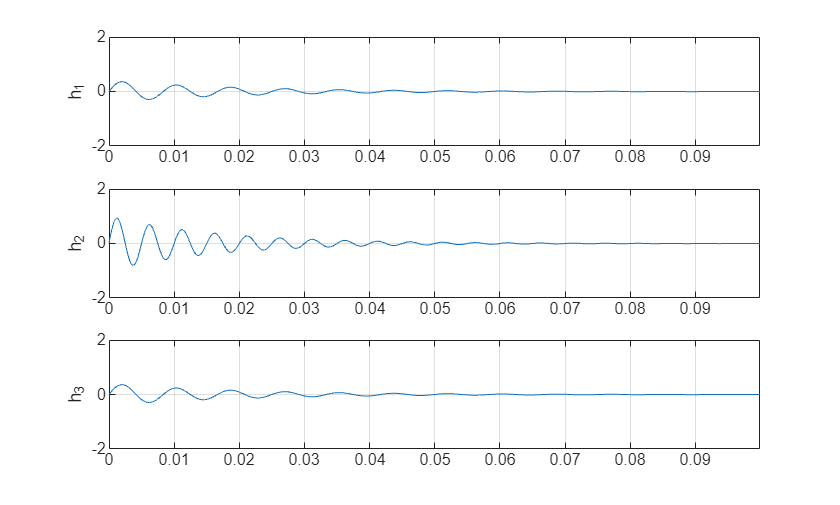

clear;

Fs = 10000;
dt = 1/Fs;
Ns = 1000;
t = (0:(Ns-1))*dt;

fre = [120 200 311];
amp = [0.4 1 0.7];
alp = [50 60 70];
pha = pi*[0.1 0.2 0.3];

M = length(fre);
sigs = zeros(M,Ns);
for m=1:M
    sigs(m,:) = amp(m)*exp(-alp(m)*t).*sin(2*pi*fre(m)*t + (pi/180)*pha(m));
end
sig = sum(sigs);


figure(1);
subplot(3,1,1);
plot(t,sigs(1,:));
axis([0 max(t) -2 2]);
grid;
ylabel('h_{1}');

subplot(3,1,2);
plot(t,sigs(2,:));
axis([0 max(t) -2 2]);
grid;
ylabel('h_{2}');

subplot(3,1,3);
plot(t,sigs(1,:));
axis([0 max(t) -2 2]);
grid;
ylabel('h_{3}');

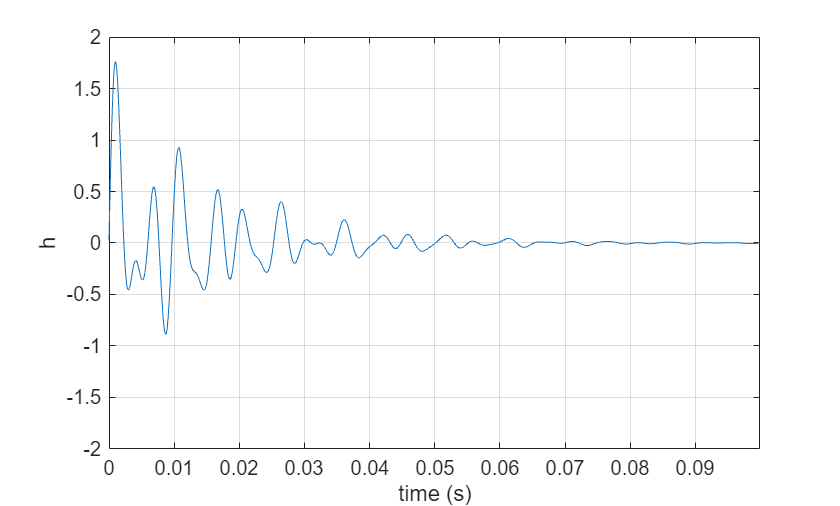

figure(2);
clf;
plot(t,sig);
axis([0 max(t) -2 2]);
grid;
xlabel('time (s)');
ylabel('h');

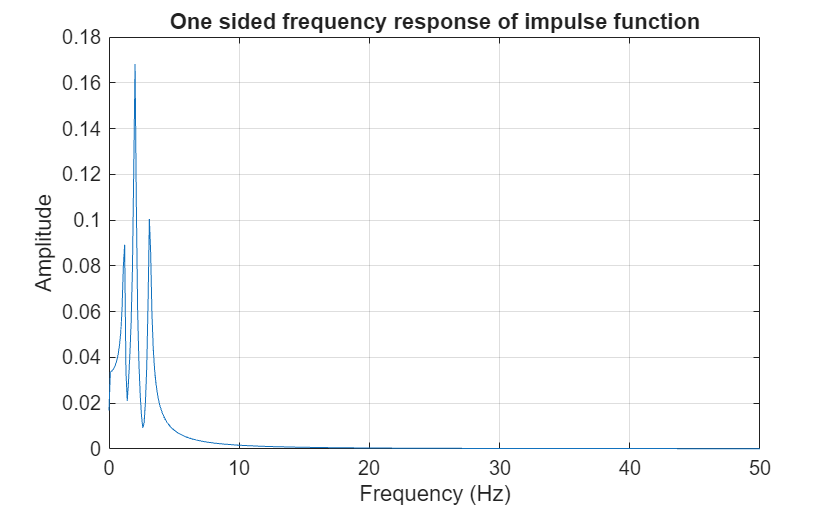

% Copy the docs for this for convenience.
frequencyResponse = fft(sig);
P2 = abs(frequencyResponse / Ns);
P1 = P2(1:Ns/2+1);
P1(2:end-1) = 2*P1(2:end-1);
frequencyAxis = (0 : (Ns / 2)) * (Ns / Fs);

figure
plot(frequencyAxis, P1)
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('One sided frequency response of impulse function')
grid;

## Step 2 - Markov Parameters

For a unit impulse input $u\left\lbrack k\right\rbrack =\delta \;\left\lbrack k\right\rbrack$ and zero initial condition $x\left\lbrack 0\right\rbrack =0$, the system $y\left\lbrack k\right\rbrack$ defines the Markov parameters:


$$y[0] = d, \\
y[1] = \mathbf{c}^\top\mathbf{b}, \\
y[k] = \mathbf{c}^\top \mathbf{A}^{k-1} \mathbf{b}, \ k \geq 2$$


This is simply the impulse response.

y = sig;

## Step 3 - Hankel Matrix construction

The Hankel matrix is defined from the impulse response as follows:


$${\mathit{\mathbf{H}}}_0 =\left\lbrack \begin{array}{cccc}
y\left\lbrack 1\right\rbrack  & y\left\lbrack 2\right\rbrack  & \cdots  & y\left\lbrack s\right\rbrack \\
y\left\lbrack 2\right\rbrack  & y\left\lbrack 3\right\rbrack  & \cdots  & y\left\lbrack s+1\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
y\left\lbrack r\right\rbrack  & y\left\lbrack r+1\right\rbrack  & \cdots  & y\left\lbrack r+s-1\right\rbrack 
\end{array}\right\rbrack$$


the shifted Hankel matrix is:


$${\mathit{\mathbf{H}}}_1 =\left\lbrack \begin{array}{cccc}
y\left\lbrack 2\right\rbrack  & y\left\lbrack 3\right\rbrack  & \cdots  & y\left\lbrack s+1\right\rbrack \\
y\left\lbrack 3\right\rbrack  & y\left\lbrack 4\right\rbrack  & \cdots  & y\left\lbrack s+2\right\rbrack \\
\vdots  & \vdots  & \ddots  & \vdots \\
y\left\lbrack r+1\right\rbrack  & y\left\lbrack r+2\right\rbrack  & \cdots  & y\left\lbrack r+s\right\rbrack 
\end{array}\right\rbrack$$


where *r* is the number of rows and *s* is the number of columns. These must be selected to appropriately capture the dynamics of the system without including noise. The details on this is very thin in the primary referece, but [3] provides several pointers:

- Approximate the number of natural frequencies - this can be done via experience, a preliminary numerical model, or by performing the cross-spectral density and counting the number of peaks.

- **Columns**: Use 4 times the number of expected modes (twice the number of poles). Forcing a low-rank Hankel matrix could lead to missing some physical vibration modes, but is useful as a starting point.

- **Rows**: Set based on the number of points available in the cross-spectral density function. The goal is to use as much information from the the CSD (cross-spectral density) as possible without including noisy signals found at the end of the CSD.

Additional points for further work - 

**Model order and stabilization diagrams:**

- If the model order is too high, fictitious modes can be included in the results.

- If the model order is too small, some modal parameters may not be identified.

- Repeat the identification process with a different number of poles each time.

**MAC and Damping Filter:**

- MAC and Damping Filter can be used to automatically identify stable modes in the stabilization diagram.

- Modes with damping ratios lower or higher than a threshold can be discarded.

- The correlation between mode shapes at a specific frequency can be compared using the MAC.

- Used to determine the similarity (linearity of one-mode shape when compared to a reference mode.

- Modal assurance ranges from 0 to 1, 0 is no consistency between the mode shaps, 1 is consistent.

- Consult the literature for the equation.

% Number of expected modes from sinusoid = 3.
columnScalingFactor = 4;
nModes = 3;
nColumns = nModes * columnScalingFactor;

% Try keeping it square first
nRows = nColumns;

H0 = zeros(nRows, nColumns);
H1 = H0;

% Provide two truncated signals for the hankel matrix construction.
yNew = y(2 : end);
yNewShift = y(3 : end);

% I need to do a better implementation of this later.
for i = 1 : nRows
    for j = 1 : nColumns

        H0(i, j) = yNew(i + j - 1);
        H1(i, j) = yNewShift(i + j - 1);

    end
end


## Step 4 - SVD and truncation

For the relatively simple example explored in this notebook, it can be observed in the S matrix that the number of singular values to keep would be 6. This corresponds to both the real and complex parts of the modes used to construct the impulse response. This is easily observed in the data as the entries in the S matrix go to 0 after S(6,6).

[U, S, V] = svd(H0);

% Number of singular values to keep. Should be double the expected number
% of modes.
m = 2 * nModes;

% Here I am going to manually select the largest singular values, but will
% likely need to set some sort of threshold in the future to select this.
Sm = S(1 : m, 1 : m);

% Left and right singular vectors. From my understanding, if you select m
% modes, you must also select m singular vectors (these should all be
% columns irrespective of U or V as MATLAB returns V, not VT - this caused
% some confusion).
Um = U(:, 1 : m);

Vm = V(:, 1 : m);


## Step 5 - Reconstruct state space matrices

Reconstruct the esimated state space matrices using the truncated singular value decomposition of the base Hankel matrix and the shifted Hankel matrix:


$$\mathbf{\hat{A}} = \mathbf{\Sigma}_{m}^{-1/2} \mathbf{U}_m \mathbf{H}_1 \mathbf{V}_m \mathbf{\Sigma}_{m}^{-1/2}, \\
\mathbf{\hat{b}} = \mathbf{\Sigma}_{m}^{1/2} \mathbf{V}_m^{T} \mathbf{e}_{1}^{(s)}, \\
\mathbf{\hat{c}} = \mathbf{\Sigma}_{m}^{1/2} \mathbf{U}_{m}^{T} \mathbf{e}_{1}^{(r)}, \\
\hat{d} = y[0], $$


where $\mathbf{e}_{1}^{(\ell)} = [1, 0, ..., 0]^T$ is the first canoncial basis vector of dimension $\ell$. This will yield,


$$\mathbf{\hat{x}}[k+1] = \mathbf{\hat{A}} \mathbf{\hat{x}} [k] + \mathbf{\hat{b}} u[k], \\
\hat{y} [k] = \mathbf{\hat{c}}^T \mathbf{\hat{x}} [k] + \hat{d} u[k].$$


% For this example, these are the same vector, but the creation of two
% separate vectors and the notation used are kept the same in order to
% align with the paper implementation if the Hankel matrix is not square.
es = zeros(nColumns, 1);
es(1) = 1;

er = zeros(nRows, 1);
er(1) = 1;

% S half and S inverse.
singularValues = diag(Sm);

sHalf = diag(sqrt(singularValues));       % S^(+1/2)
sHalfInv = diag(1 ./ sqrt(singularValues));  % S^(-1/2)

% Creation of the state space matrices.
Ahat = sHalfInv * Um' * H1 * Vm * sHalfInv;
Bhat = sHalf * Vm' * es;
Chat = sHalf * Um' * er;
DHat = y(1);

## Step 6 - Modal parameter extraction

Note: These are very easy modes to separate out, could there be two stages of filtering? In the FDM method, there are thresholds for each of the parameters below. Maybe this could be implemented as an additional step to ensure there are no noise modes selected? That way you can oversample the number of modes in the SVD step, this might be defeating the point of it though, not sure, need to think about it a bit more.

[eigenVectors, eigenValues] = eig(Ahat);

% Continuous time eigenvalues, taken from ETH Zurich powerpoint [3].
lambda = log(eigenValues) ./ dt;
% Have to clean up these entries so the later steps work. Noticed this in
% an old tutorial example with SVD as well.
lambda(isinf(lambda)) = 0;

% Same as above, taken from Zurich.
frequencies = abs(lambda) ./ (2 * pi);

% Damping factor calculation.
zeta = -real(lambda) ./ abs(lambda);

% Stick in a transpose here as C is technically supposed to be a row in all the Control systems examples anyway.
modes = Chat' * eigenVectors;

## Step 7 - Reconstruct the impulse response.

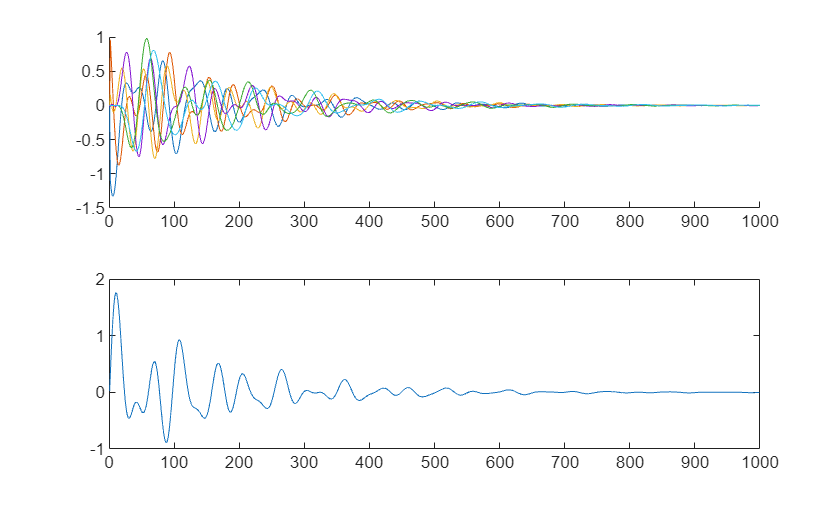

% Preallocation here, descriptors as follows:
% x - 2 * nModes, covers the real and imaginary components of the
%   associated frequencies.
% yHat - output, scalar.
% u - input, unit impulse function.
x = zeros(m, Ns);
yHat = zeros(1, Ns - 1);
u = zeros(Ns, 1);
u(1) = 1;

% Naive implementation, will fix this later, good enough for now.
for k = 1 : Ns - 1
    x(:, k + 1) = Ahat * x(:, k) + Bhat * u(k);
    yHat(k) = Chat' * x(:, k) + DHat * u(k);
end

figure
tiledlayout(2, 1)
nexttile
hold on
for i = 1 : m
    plot(x(i, :), 'DisplayName', "Mode number: " + string(i))
end

nexttile
plot(yHat)

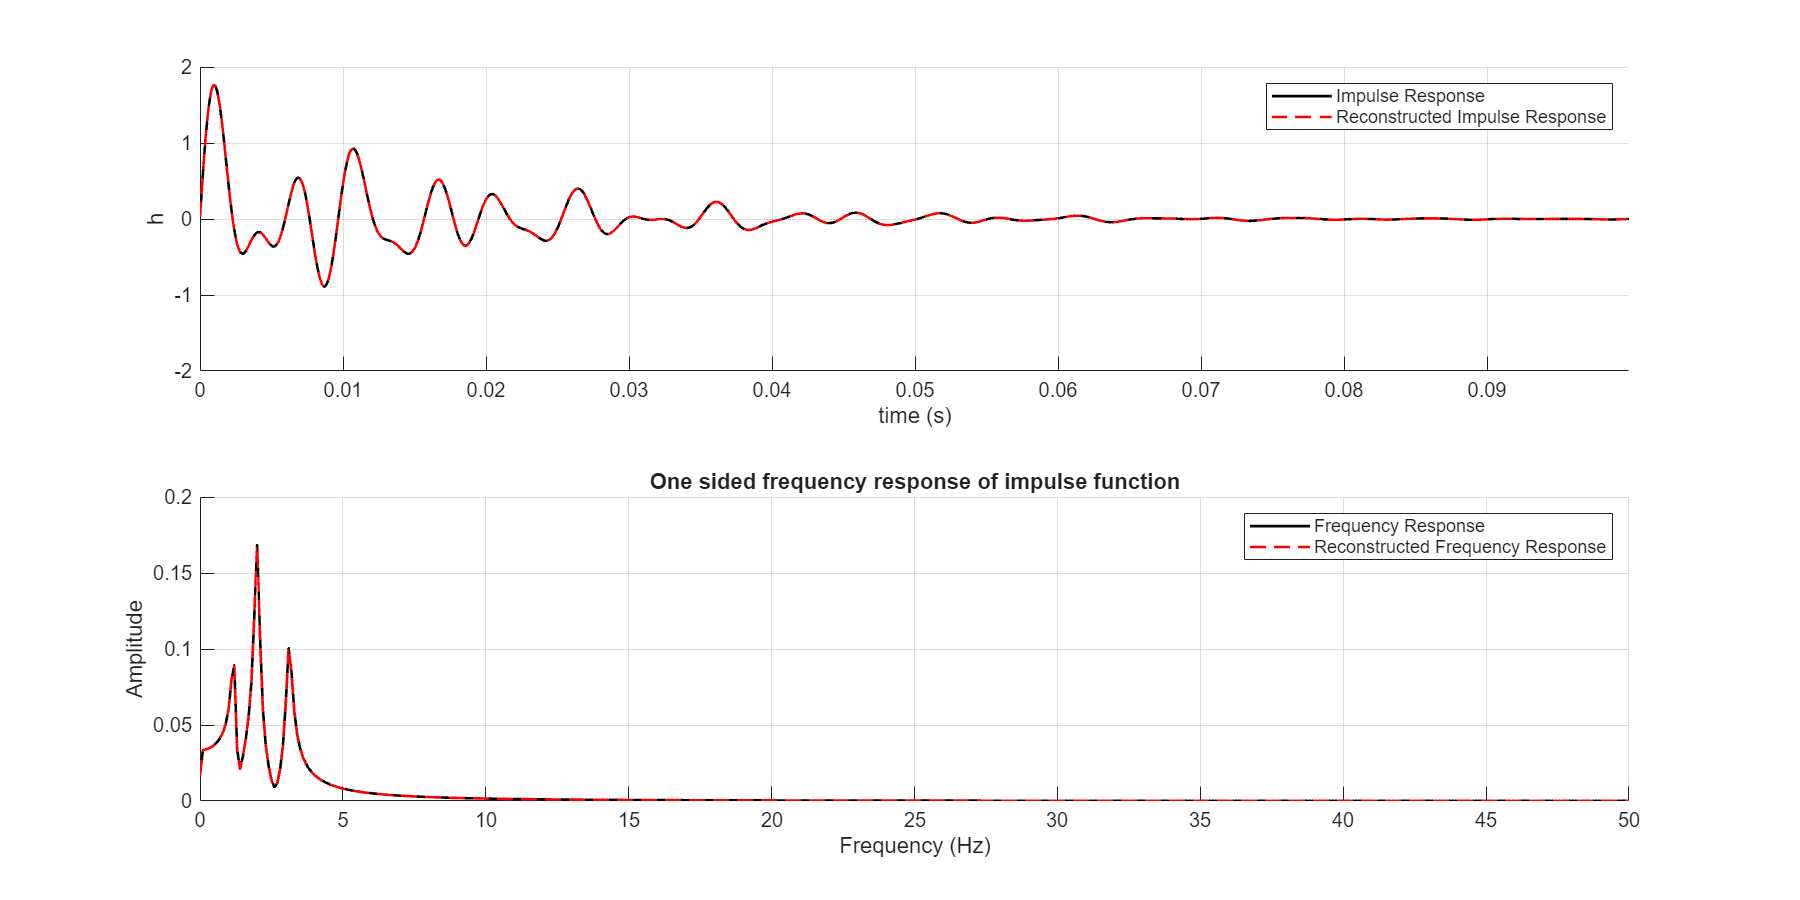

f = figure;
f.Position = [0 0 1200 600];
tiledlayout(2, 1);

nexttile
hold on
plot(t, y, 'k', 'LineWidth', 1.3, 'DisplayName', 'Impulse Response');
axis([0 max(t) -2 2]);
grid;
xlabel('time (s)');
ylabel('h');

plot(t(1 : end -1), yHat, 'r--', 'LineWidth', 1.3, 'DisplayName', 'Reconstructed Impulse Response')
legend

nexttile
hold on
plot(frequencyAxis, P1, 'k', 'LineWidth', 1.3, 'DisplayName', 'Frequency Response')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('One sided frequency response of impulse function')
grid;

frequencyResponse2 = fft(yHat);
P2_2 = abs(frequencyResponse2 / Ns);
P1_2 = P2_2(1:Ns/2+1);
P1_2(2:end-1) = 2*P1_2(2:end-1);
frequencyAxis_2 = (0 : (Ns / 2)) * (Ns / Fs);
plot(frequencyAxis_2, P1_2, 'r--', 'LineWidth', 1.3, 'DisplayName', 'Reconstructed Frequency Response')
legend

Proof of concept. Need to apply multiple modes at one frequency and some noise. Following this, applying to real signals will introduce the challenge of mode order selection for cello bridge measurements.

## Step 7 - Part 2: Diagonalisation

### Mathematical background

Notes are stitched together from [4, 5, 6]

Theory:

There are infinitely many different forumulations of the state space matrices $\mathbf{\hat{A}}, \mathbf{\hat{b}}, \mathbf{\hat{c}},\hat{d}$. there exists a linear transformation:


$$\mathbf{\hat{A_z}} = \mathbf{TAT^{-1}}, \\
\mathbf{\hat{B_z}} = \mathbf{TB}, \\
\mathbf{\hat{C_z}} = \mathbf{CT^{-1}}, \\
\mathbf{\hat{D_z}} = \mathbf{D}$$


which will also represent the system as the transfer function is unique [4].

Given this, the retrieved state space matrix $\mathbf{\hat{A}}
$can be diagonalised (eigen-decomposition), which is a similarity transformation yielded by the matrix of eigenvectors of $\mathbf{\hat{A}}
$ [5].

A singular eigenvector $\underline{e}_i$ of $\mathbf{\hat{A}}
$ satisfies the relationship


$$\mathbf{\hat{A}}\underline{e}_i = \lambda_i \underline{e}_i$$


where $\underline{e}_i$ and $\lambda_i$ may be complex.

A state space model is diagonalised by a similarity transformation (transformed to modal form) by a matrix $\mathbf{Q}
$ whose columns are defined by the eigenvectors of $\mathbf{\hat{A}}$:


$$\mathbf{Q} = [\underline{e}_1 \dots \underline{e}_N]$$


A system may be diagonalised when the eigenvectors are linearly independant. This always holds for distinct poles.

(Note: We have complex conujgate pair in the poles for second order systems, these are distinct poles, does not require Jordan blocks).

If the eigenvectors of $\mathbf{\hat{A}}
$ are full rank, $\mathbf{Q}$ is full rank, so it can be inverted. This means it is a one-to-one, and qualifies as a linear transformation matrix.

The transformation is given as follows:


$$\mathbf{\hat{A}} = \mathbf{Q}^{-1} \Lambda \mathbf{Q}$$


As $\mathbf{\hat{A}}\underline{e}_i = \lambda_i \underline{e}_i$, this yields:


$$\mathbf{\hat{A}}\mathbf{Q} = \mathbf{Q}\Lambda$$


where $\Lambda$ is a diagonal matrix with the complex eigenvalues along the diagonal.

Thus, a new transformation matrix can be constructed:


$$\mathbf{\tilde{A}} = \mathbf{Q}^{-1} \mathbf{\hat{A}} \mathbf{Q} = \mathbf{Q}^{-1} \mathbf{Q} \Lambda = \Lambda$$


### Computation

Given that $\Lambda$ is a diagonal matrix, we can further simplify the operations by keeping the eigenvalues in a column vector to propagate through the individual modes.


$$\Lambda =\left\lbrack \begin{array}{c}
\lambda_1 \\
\lambda_2 \\
\vdots \\
\lambda_N 
\end{array}\right\rbrack$$


By considering the co-ordinate transformations applied to the constructed state space representations:


$$\mathbf{\hat{x}} \leftarrow \mathbf{Q}^{-1}\mathbf{\hat{x}},
\quad \mathbf{\hat{A}} \leftarrow \Lambda,
\quad \mathbf{\hat{b}} \leftarrow \mathbf{Q}^{-1} \mathbf{\hat{b}},
\quad \mathbf{\hat{c}} \leftarrow \mathbf{Q}^{\mathbf{T}} \mathbf{\hat{c}}$$


so the state space formulae with the transformation applied becomes:


$$\mathbf{\hat{x}}[k + 1] = \Lambda \mathbf{ \hat{x}}[k] + \mathbf{Q^{-1} \hat{b}}u[k]\\
y[k] = \left( \mathbf{Q^{T} \hat{c}} \right)^\mathbf{T} \mathbf{ \hat{x}}[k] + \hat{d}u[k]$$


**Note:** I have hand calculated this out and don't see where the $\mathbf{\hat{x}}
$ transformation disappears to. It makes way more sense to ignore it.

Furthermore, from Section 2 we know that:


$$y[0] = d, \\
y[1] = \mathbf{c}^\top\mathbf{b}, \\
y[k] = \mathbf{c}^\top \mathbf{A}^{k-1} \mathbf{b}, \ k \geq 2$$


Calculating the first several terms of the recurrence relation:


$$\mathbf{\hat{x}}[1] = \Lambda \mathbf{\hat{x}}[0] + \mathbf{Q^{-1} \hat{b}}u[0], \quad u[k] = [1, 0, 0, \dots 0] \\
\therefore \quad \mathbf{\hat{x}}[1] = \mathbf{Q^{-1} \hat{b} \\
\mathbf{\hat{x}}[2] = \Lambda \mathbf{Q^{-1} \hat{b}} \\
\mathbf{\hat{x}}[3] = \Lambda^2 \mathbf{Q^{-1} \hat{b}} \\
\mathbf{\hat{x}}[4] = \Lambda^3 \mathbf{Q^{-1} \hat{b}}$$


demonstrating that the states are defined by the relation:


$$\mathbf{\hat{x}}[k] =  \Lambda^{k-1} \mathbf{Q^{-1} \hat{b}}, \ k \geq 1$$


the outputs are then defined as follows:


$$\hat{y}[0] = (\mathbf{Q}^{\top} \mathbf{\hat{c}})^\top \mathbf{\hat{x}}[0] + \hat{d}u[0], \\ 
\therefore \quad \hat{y}[0] = \hat{d} \\
\hat{y}[1] = (\mathbf{Q}^{\top} \mathbf{\hat{c}})^\top \mathbf{Q^{-1} \hat{b}} \\
\hat{y}[2] = (\mathbf{Q}^{\top} \mathbf{\hat{c}})^\top \Lambda \mathbf{Q^{-1} \hat{b}} \\
\hat{y}[3] = (\mathbf{Q}^{\top} \mathbf{\hat{c}})^\top \Lambda^2 \mathbf{Q^{-1} \hat{b}}$$


so $\hat{y}[k]$ is defined by:


$$\hat{y}[k] = (\mathbf{Q}^\top \mathbf{\hat{c}})^\top \Lambda^{k-1} \mathbf{Q^{-1} \hat{b}}, \ k \geq 2$$


Make substitutions so that it's easier to follow:


$$\mathbf{Q}^{-1} \mathbf{\hat{b}} = \mathbf{\tilde{b}}, \quad 
\mathbf{Q}^{\top} \mathbf{\hat{c}} = \mathbf{\tilde{c}}, \quad
\Lambda = \mathbf{\tilde{A}},  \\
\mathbf{\tilde{x}}[k + 1] =  \mathbf{\tilde{A}}^{k-1}\mathbf{\tilde{b}}, \\
\tilde{y}[k] =  \mathbf{\tilde{c}}\mathbf{\tilde{A}}^{k-1}\mathbf{\tilde{b}}, \quad k \geq 1 \\
$$


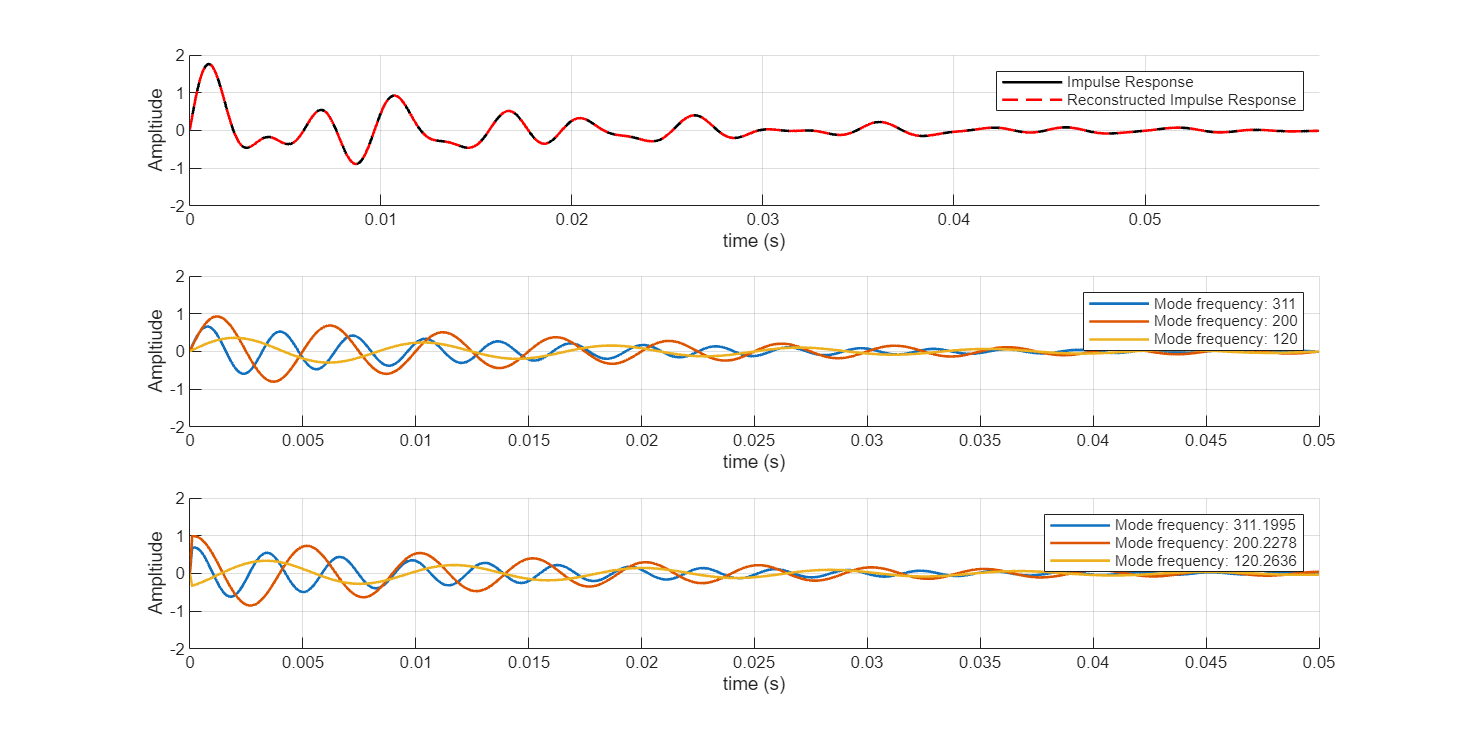

% Transform the state space representations.

% Eigenvalues, note the captial here as lowercase lambda was defined
% earlier for continuous time. These steps will be addressed in the full
% pipeline.
Atilde = diag(eigenValues);

% Apply the co-ordinate transformations from the DAFx paper.
Btilde = eigenVectors \ Bhat;

Ctilde = eigenVectors' * Chat;

% As the system becomes a propagation of the Ahat matrix based on the
% initial condition (Ahat ^ k-1), build up the matrix based on the powers of
% eigenvalues, as these are in a column vector. This is just lambda^k-1.
nPowers = 0 : Ns - 2;
L = Atilde(:) .^ nPowers;

% These are the corresponding states output using the diagonalisation.
xTilde = L .* Btilde(:);

% As we must represent a real signal with complex numbers (or negative
% frequencies), we only consider the real part of the output. To reconcile
% this in my head the transformation goes as follows:
% inputs signal [REAL] -> State Space [COMPLEX] -> output signal [REAL].
% Once again, the transpose is here to align with DAFx paper
% implementation.
yTilde = real(Ctilde' * xTilde);

% A little bit of linear algebra to calculate out individual modes.
% Elementwise multiplication keeps modes separate.
% IMPORTANT NOTE: Recall that the modes are represented by complex
% conjugate pairs. If we want to recover the proper amplitude, either add
% the modes together i.e., individualModes(1, :) + individualModes(2, :),
% or just double the odd row indexes.
individualModes = real(Ctilde .* xTilde);

% To recover the impulse response properly, we must stitch on the first
% sample.
yTilde = [y(1) yTilde];

f = figure;
f.Position = [0 0 1200 600];
til = tiledlayout(3, 1);
t1 = nexttile;
t2 = nexttile;
t3 = nexttile;

hold(t1, "on")
hold(t2, "on")
hold(t3, "on")

plot(t1, t, y, 'k', 'LineWidth', 1.3, 'DisplayName', 'Impulse Response');
plot(t1, t, yTilde, 'r--', 'LineWidth', 1.3, 'DisplayName', 'Reconstructed Impulse Response')
axis(t1, [0 max(t) -2 2]);
grid(t1, "on");
xlabel(t1, 'time (s)');
ylabel(t1, 'Ampltiude');
legend(t1);

for i = 3 : -1 : 1
    plot(t2, t, sigs(i, :), 'LineWidth', 1.3, 'DisplayName', "Mode frequency: " + string(fre(i)))
end
axis(t2, [0 max(t) -2 2]);
grid(t2, "on");
xlabel(t2, 'time (s)');
ylabel(t2, 'Ampltiude');
legend(t2);

% Note: The system response is calculated with respect to the initial
% conditions = 0. This means recovering the modal representations must have
% the 0 entry stitched on to the start of each mode, similar to the initial
% condition of the output signal.
for i = 1 : 2 : 6
    plot(t3, t, [0 (individualModes(i, :) + individualModes(i + 1, :))], 'LineWidth', 1.3, 'DisplayName', "Mode frequency: " + string(frequencies(i, i)))
end
axis(t3, [0 max(t) -2 2]);
grid(t3, "on");
xlabel(t3, 'time (s)');
ylabel(t3, 'Ampltiude');
legend(t3);

xlim([t1, t2, t3], [0 0.05])

normalisedMeanSquareError = sum(((y - yTilde).^2)) ./ sum(y.^2);

fprintf("The normalised mean square error of the impulse response reconstruction is: %.4d", normalisedMeanSquareError)

The normalised mean square error of the impulse response reconstruction is: 1.3395e-12

Modal reconstruction seems to reconstruct with cosines as opposed to sine wave, 90 degree phase shift possibly.

% Test
opts = eraConfig();
opts.svdTolerance = 3;

[outputSignal, frequencies, dampingFactors, modes] = ...
    eigensystemRealisation(y, nModes, nRows, nColumns, Fs, opts);

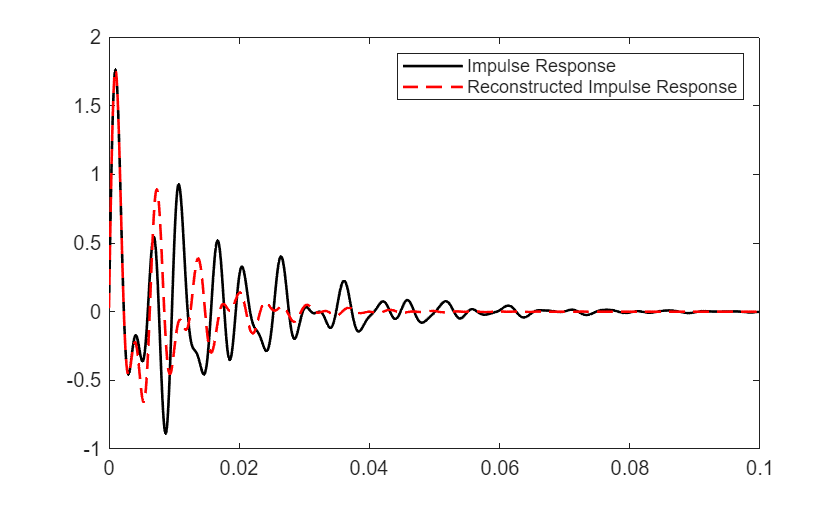


figure
plot(t, y, 'k', 'LineWidth', 1.3, 'DisplayName', 'Impulse Response')
hold on
plot(t, outputSignal, 'r--', 'LineWidth', 1.3, 'DisplayName', 'Reconstructed Impulse Response')
legend

## Imported Code

This is the FDM code. Imported to step through and see how it operates.

% clear;

F_compute = 1;      % set to 1 to actually perform the FDM calculation

if F_compute
    data = load('data1.mat');
    tf = (data.data(:,1))';
    hf = (data.data(:,2))';
    Fs = 40000;
    Nsf = length(hf);
    Ns = 3000;      % truncated signal for estimation
    h = hf(1:Ns);
    t = tf(1:Ns);
    fmin = 0;
    fmax = 3000;
    
    Hf = fft(hf);
    ff = (0:(Nsf-1))*(Fs/Nsf);

    [freE,groE,ampE,phaE] = fdm_FAST(h,Fs,fmin,fmax,1);
    save('data1.mat');
else
    load('data1.mat');
end

Index in position 2 exceeds array bounds. Index must not exceed 1.


ampE = 2*ampE;      % correct for 2*cos(X) = exp(+j*X) + exp(-j*X)
alpE = -groE;       % flip growth to obtain attenuation
phaE = phaE + 90;   % correct for sin rather than cos
ii = find(phaE > 180);  % ensure phase lying in [-180,180]
phaE(ii) = phaE(ii) - 360;
Amax = max(ampE);
ampE = ampE/Amax;       % normalise such that max amp = 1
LdB = 60;            % threshold level in dB (compare to 0 dB for maximum amp)
LEVEL = 10^(-LdB/20);

%% REMOVING SPURIOUS COMPONENTS %%%%%
ii = find(alpE > 0);                   % not growing
freE = freE(ii); ampE = ampE(ii); alpE = alpE(ii); phaE = phaE(ii); 

freES = freE; ampES = ampE; alpES = alpE; phaES = phaE; 
ii = find(freES > fmin & freES < fmax); % within analysis band
freES = freES(ii); ampES = ampES(ii); alpES = alpES(ii); phaES = phaES(ii); 

ii = find(ampES > LEVEL);                % significant amplitude
freES = freES(ii); ampES = ampES(ii); alpES = alpES(ii); phaES = phaES(ii); 

%% MODAL RE-SYNHESIS %%%%%%%%%%%%%%%%
MES = length(freES);
hES = zeros(1,Nsf);
for m=1:MES
    hES = hES + ampES(m)*exp(-alpES(m)*tf).*sin(2*pi*freES(m)*tf + (pi/180)*phaES(m));
end
hES = Amax*hES;     % restore original amplitude
HES = fft(hES);

HF = figure(1);
clf;
set(HF,'position',[500 100 1000 900]);


subplot(4,1,1)
ax1 = plot(freE,20*log10(ampE),'o','markersize',4);
hold on;
ax2 = plot(freES,20*log10(ampES),'x','markersize',4);
plot([0 fmax*1.5],-LdB*[1 1],'k--');
hold off;
grid;
xlim([0 fmax*1.5]);
ylabel('amplitude (dB)');
xlabel('frequency (Hz)');
legend([ax1 ax2],'all','selection');
title([ num2str(MES) ' oscillators selected for re-synthesis' ]);

subplot(4,1,2)
ax1 = semilogy(freE,alpE,'o','markersize',4);
hold on;
ax2 = semilogy(freES,alpES,'x','markersize',4);
hold off;
grid;
xlim([0 fmax*1.5]);
ylabel('decay rate (1/m)');
xlabel('frequency (Hz)');
legend([ax1 ax2],'all','selection');


subplot(4,1,3)
plot(ff,20*log10(abs(Hf)),ff,20*log10(abs(HES)));
grid;
xlim([0 fmax*1.5]);
ylabel('amplitude (dB)');
xlabel('frequency (Hz)');
ylim([-80 -30]);
legend('measured','resynthesis');

subplot(4,1,4)
plot(tf,hf,tf,hES);
grid;
xlim([0 max(t)]);
ylabel('amplitude');
xlabel('time (s)');
ylim(1.5*max(abs(hf))*[-1 1]);
legend('measured','resynthesis');

## Subfunctions

Pending.

## References

[1] R. S. Pappa and J.-N. Juang, “Galileo spacecraft modal iden-

tification using an eigensystem realization algorithm,” in

25th Structures, Structural Dynamics and Materials Confer-

ence, 1984, pp. 630–645.

[2] J.-N. Juang and R. S. Pappa, “An eigensystem realization al-

gorithm for modal parameter identification and model reduc-

tion,” Journal of Guidance, Control, and Dynamics, vol. 8,

no. 5, pp. 620–627, 1985.

[3] J. M. Caicedo, “PRACTICAL GUIDELINES FOR THE NATURAL EXCITATION  TECHNIQUE (NExT) AND THE EIGENSYSTEM REALIZATION ALGORITHM (ERA) FOR  MODAL IDENTIFICATION USING AMBIENT VIBRATION,” Experimental Techniques,  vol. 35, no. 4, pp. 52–58, Jun. 2010, doi:  10.1111/j.1747-1567.2010.00643.x.

[4] N. Athanasopoulos, "Control 101: Uniqueness of Representation", Queen's University Belfast, Accessed 18/06/2026

[5] J. Smith, “MUS420 Introduction to Modal Representations State Space Modal Representation,” 2019. Accessed: Jun. 18, 2026. [Online]. Available: [https://ccrma.stanford.edu/~jos/ModalRep/ModalRep_4up.pdf](https://ccrma.stanford.edu/~jos/ModalRep/ModalRep_4up.pdf)